# Processing of initial data

### Import .mat file

Clear the Matlab workspace of all values.

clear;clc

Import the .mat file containing the data of the flight. This contains the flight's callsign, type of aircraft used, time of arrival (converted from hours:minutes:seconds to time with respect to the first flight), route, and initial indicated air speed (IAS). Convert the imported file into cell *flights_data*.

flights_cell = importdata("May192023data.mat");
% flights_cell = importdata("Jul142023data.mat");
% flights_cell = importdata("Nov012022data.mat");

flights_data = table2cell(flights_cell);

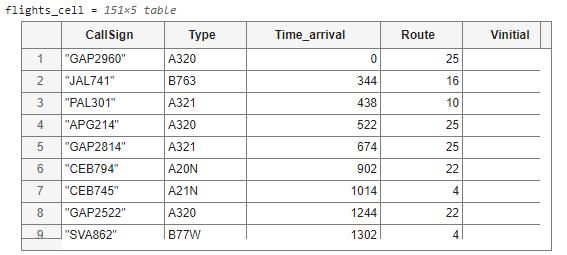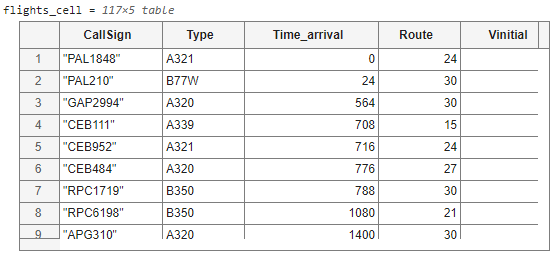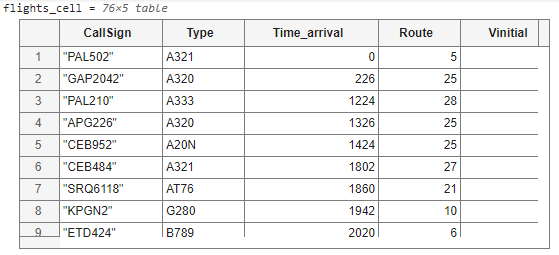

Import *Routes.mat* generated from **Waypoints data processing*****.***

Routes = importdata("Routes.mat");

### Data processing

Based on the route number in *flights_data*, create a new column (6) to store the route details. Save the updated *flights_data*.

col4_basis = [flights_data{:, 4}];

% Assign the 6th column to store Route points
flights_data(:, 6) = cell(size(flights_data, 1), 1);
for i = 1:length(col4_basis)
    flights_data{i, 6} = Routes{col4_basis(i)};
end

for i = 1:length(flights_data)
    additionalData = flights_data{i, 6};
    additionalData{1, 5} = flights_data{i, 3}; 
    additionalData{1, 6} = flights_data{i, 5}; 
    flights_data{i, 6} = additionalData;
end

for i = 1:length(flights_data)
    for j = 1:length(flights_data{i,6})
        if isempty(flights_data{i, 6}{j,5})
            flights_data{i, 6}{j,5} = 0;
        end
        if isempty(flights_data{i, 6}{j,6})
            flights_data{i, 6}{j,6} = 0;
        end
    end
end
save('flights_data.mat', 'flights_data');

Assign and save *obs* to contain the flight details.

for i = 1:size(flights_data, 1)
    col6_flights_data = flights_data{i, 6};                     

    var_name = ['flights_data' num2str(i)];                     
    eval([var_name ' = col6_flights_data']);
    
    fileName = fullfile('Testing_data', [num2str(i) '.mat']);  
    save(fileName, var_name);
end

flights_data1 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[0]}    {[345]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.2220]}    {[92.5999]}    {[0]} 

flights_data2 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[344]}    {[330]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2220]}    {[92.5999]} 

flights_data3 = 67×6 cell array
    {[-5.4212e+04]}    {[1.0597e+05]}    {[257.2220]}    {[92.5999]}    {[438]}    {[425]}
    {[-5.1350e+04]}    {[1.0194e+05]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[-4.8488e+04]}    {[9.7906e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[-4.5625e+04]}    {[9.3875e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[-4.2763e+04]}    {[8.9845e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[-3.9901e+04]}    {[8.5814e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[-3.7039e+04]}    {[8.1783e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[-3.4176e+04]}    {[7.7752e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[-3.1314e+04]}    {[7.3721e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[-2.8452e+04]}    {[6.9690e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[-2.5590e+04]}    {[6.5660e+04]}    {[257.2220]}    {

flights_data4 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[522]}    {[340]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.2220]}    {

flights_data5 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[674]}    {[345]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.2220]}    {

flights_data6 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[902]}    {[375]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[  0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}    {[257.2220]}    {

flights_data7 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[1014]}    {[435]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.3981e+04]}    {[-3.9101e+04]}

flights_data8 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[1244]}    {[365]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}    {[257.2

flights_data9 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[1302]}    {[395]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.3981e+04]}    {[-3.9101e+04]}

flights_data10 = 67×6 cell array
    {[-5.4212e+04]}    {[1.0597e+05]}    {[257.2220]}    {[92.5999]}    {[1590]}    {[345]}
    {[-5.1350e+04]}    {[1.0194e+05]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.8488e+04]}    {[9.7906e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.5625e+04]}    {[9.3875e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.2763e+04]}    {[8.9845e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.9901e+04]}    {[8.5814e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.7039e+04]}    {[8.1783e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.4176e+04]}    {[7.7752e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.1314e+04]}    {[7.3721e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-2.8452e+04]}    {[6.9690e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-2.5590e+04]}    {[6.5660e+04]}    {[257.

flights_data11 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[1902]}    {[320]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.

flights_data12 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[1938]}    {[360]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2220]}    {

flights_data13 = 67×6 cell array
    {[ -492.5329]}    {[1.0715e+05]}    {[257.2220]}    {[92.5999]}    {[2556]}    {[330]}
    {[2.3681e+03]}    {[1.0340e+05]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.2288e+03]}    {[9.9647e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.0894e+03]}    {[9.5897e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.0950e+04]}    {[9.2147e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.3811e+04]}    {[8.8397e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.6671e+04]}    {[8.4647e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.9532e+04]}    {[8.0897e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.2393e+04]}    {[7.7147e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.5253e+04]}    {[7.3397e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8114e+04]}    {[6.9646e+04]}    {[257.2220]}    {

flights_data14 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[2692]}    {[365]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.

flights_data15 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[2800]}    {[350]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2220]}    {

flights_data16 = 67×6 cell array
    {[-5.4212e+04]}    {[1.0597e+05]}    {[257.2220]}    {[92.5999]}    {[2810]}    {[400]}
    {[-5.1350e+04]}    {[1.0194e+05]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.8488e+04]}    {[9.7906e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.5625e+04]}    {[9.3875e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.2763e+04]}    {[8.9845e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.9901e+04]}    {[8.5814e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.7039e+04]}    {[8.1783e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.4176e+04]}    {[7.7752e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.1314e+04]}    {[7.3721e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-2.8452e+04]}    {[6.9690e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-2.5590e+04]}    {[6.5660e+04]}    {[257.

flights_data17 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[2850]}    {[365]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.3981e+04]}    {[-3.9101e+04]

flights_data18 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[3204]}    {[380]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.

flights_data19 = 67×6 cell array
    {[-6.3984e+04]}    {[9.9696e+04]}    {[257.2220]}    {[92.5999]}    {[3618]}    {[365]}
    {[-6.0546e+04]}    {[9.6524e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.7108e+04]}    {[9.3351e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.3670e+04]}    {[9.0179e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.0232e+04]}    {[8.7007e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.6794e+04]}    {[8.3835e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.3356e+04]}    {[8.0662e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.9918e+04]}    {[7.7490e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.6480e+04]}    {[7.4318e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.3042e+04]}    {[7.1146e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-2.9604e+04]}    {[6.7973e+04]}    {[257.

flights_data20 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[3636]}    {[350]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}    {[257.

flights_data21 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[3696]}    {[330]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2220]}    {

flights_data22 = 67×6 cell array
    {[-4.8340e+04]}    {[-1.0106e+05]}    {[257.2220]}    {[92.5999]}    {[4160]}    {[260]}
    {[-4.8947e+04]}    {[-9.6155e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.9555e+04]}    {[-9.1248e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.0162e+04]}    {[-8.6341e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.0770e+04]}    {[-8.1434e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.1377e+04]}    {[-7.6527e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.1985e+04]}    {[-7.1620e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.2592e+04]}    {[-6.6713e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.3200e+04]}    {[-6.1806e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.3807e+04]}    {[-5.6899e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.4415e+04]}    {[-5.1992e+04]

flights_data23 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[4192]}    {[265]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.3981e+04]}    {[-3.9101e+04]

flights_data24 = 67×6 cell array
    {[ -492.5329]}    {[1.0715e+05]}    {[257.2220]}    {[92.5999]}    {[4272]}    {[335]}
    {[2.3681e+03]}    {[1.0340e+05]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.2288e+03]}    {[9.9647e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.0894e+03]}    {[9.5897e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.0950e+04]}    {[9.2147e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.3811e+04]}    {[8.8397e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.6671e+04]}    {[8.4647e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.9532e+04]}    {[8.0897e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.2393e+04]}    {[7.7147e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.5253e+04]}    {[7.3397e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8114e+04]}    {[6.9646e+04]}    {[257.2220]}    {

flights_data25 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[4376]}    {[355]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.

flights_data26 = 67×6 cell array
    {[-4.8340e+04]}    {[-1.0106e+05]}    {[257.2220]}    {[92.5999]}    {[4556]}    {[350]}
    {[-4.8947e+04]}    {[-9.6155e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.9555e+04]}    {[-9.1248e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.0162e+04]}    {[-8.6341e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.0770e+04]}    {[-8.1434e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.1377e+04]}    {[-7.6527e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.1985e+04]}    {[-7.1620e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.2592e+04]}    {[-6.6713e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.3200e+04]}    {[-6.1806e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.3807e+04]}    {[-5.6899e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.4415e+04]}    {[-5.1992e+04]

flights_data27 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[4798]}    {[400]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.3981e+04]}    {[-3.9101e+04]

flights_data28 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[5042]}    {[330]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.3981e+04]}    {[-3.9101e+04]

flights_data29 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[5464]}    {[355]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.

flights_data30 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[5796]}    {[355]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]}    {[257.

flights_data31 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[5888]}    {[325]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}    {[257.

flights_data32 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[5900]}    {[360]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]}    {[257.

flights_data33 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[5984]}    {[380]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.

flights_data34 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[6580]}    {[385]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]}    {[257.

flights_data35 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[6628]}    {[330]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}    {[257.

flights_data36 = 67×6 cell array
    {[-4.8340e+04]}    {[-1.0106e+05]}    {[257.2220]}    {[92.5999]}    {[6744]}    {[250]}
    {[-4.8947e+04]}    {[-9.6155e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.9555e+04]}    {[-9.1248e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.0162e+04]}    {[-8.6341e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.0770e+04]}    {[-8.1434e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.1377e+04]}    {[-7.6527e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.1985e+04]}    {[-7.1620e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.2592e+04]}    {[-6.6713e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.3200e+04]}    {[-6.1806e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.3807e+04]}    {[-5.6899e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-5.4415e+04]}    {[-5.1992e+04]

flights_data37 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[6930]}    {[345]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}    {[257.

flights_data38 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[6932]}    {[355]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]}    {[257.

flights_data39 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[7386]}    {[350]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.3981e+04]}    {[-3.9101e+04]

flights_data40 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[7730]}    {[380]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.

flights_data41 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[8226]}    {[395]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.

flights_data42 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[8484]}    {[390]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-6.3981e+04]}    {[-3.9101e+04]

flights_data43 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[8600]}    {[365]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}    {[257.

flights_data44 = 67×6 cell array
    {[ -492.5329]}    {[1.0715e+05]}    {[257.2220]}    {[92.5999]}    {[8696]}    {[325]}
    {[2.3681e+03]}    {[1.0340e+05]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[5.2288e+03]}    {[9.9647e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.0894e+03]}    {[9.5897e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.0950e+04]}    {[9.2147e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.3811e+04]}    {[8.8397e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.6671e+04]}    {[8.4647e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[1.9532e+04]}    {[8.0897e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.2393e+04]}    {[7.7147e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.5253e+04]}    {[7.3397e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8114e+04]}    {[6.9646e+04]}    {[257.2220]}    {

flights_data45 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[8940]}    {[345]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.

flights_data46 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[9112]}    {[255]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]}    {[257.

flights_data47 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[9256]}    {[360]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.

flights_data48 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[9318]}    {[380]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}    {[257.

flights_data49 = 67×6 cell array
    {[-5.4212e+04]}    {[1.0597e+05]}    {[257.2220]}    {[92.5999]}    {[9948]}    {[390]}
    {[-5.1350e+04]}    {[1.0194e+05]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.8488e+04]}    {[9.7906e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.5625e+04]}    {[9.3875e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-4.2763e+04]}    {[8.9845e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.9901e+04]}    {[8.5814e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.7039e+04]}    {[8.1783e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.4176e+04]}    {[7.7752e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-3.1314e+04]}    {[7.3721e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-2.8452e+04]}    {[6.9690e+04]}    {[257.2220]}    {[92.5999]}    {[   0]}    {[  0]}
    {[-2.5590e+04]}    {[6.5660e+04]}    {[257.

flights_data50 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[10110]}    {[355]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-3

flights_data51 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[10278]}    {[415]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}

flights_data52 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[10412]}    {[370]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}

flights_data53 = 67×6 cell array
    {[-6.3984e+04]}    {[9.9696e+04]}    {[257.2220]}    {[92.5999]}    {[10472]}    {[440]}
    {[-6.0546e+04]}    {[9.6524e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.7108e+04]}    {[9.3351e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3670e+04]}    {[9.0179e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0232e+04]}    {[8.7007e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.6794e+04]}    {[8.3835e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.3356e+04]}    {[8.0662e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9918e+04]}    {[7.7490e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.6480e+04]}    {[7.4318e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.3042e+04]}    {[7.1146e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.9604e+04]}    {[6.7973e+04]}

flights_data54 = 67×6 cell array
    {[-5.4212e+04]}    {[1.0597e+05]}    {[257.2220]}    {[92.5999]}    {[10580]}    {[395]}
    {[-5.1350e+04]}    {[1.0194e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.8488e+04]}    {[9.7906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.5625e+04]}    {[9.3875e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.2763e+04]}    {[8.9845e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9901e+04]}    {[8.5814e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.7039e+04]}    {[8.1783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.4176e+04]}    {[7.7752e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.1314e+04]}    {[7.3721e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.8452e+04]}    {[6.9690e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.5590e+04]}    {[6.5660e+04]}

flights_data55 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[10592]}    {[365]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}

flights_data56 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[10748]}    {[360]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-3

flights_data57 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[10752]}    {[365]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}

flights_data58 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[11156]}    {[410]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}

flights_data59 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[11222]}    {[345]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}

flights_data60 = 67×6 cell array
    {[-5.4212e+04]}    {[1.0597e+05]}    {[257.2220]}    {[92.5999]}    {[11332]}    {[340]}
    {[-5.1350e+04]}    {[1.0194e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.8488e+04]}    {[9.7906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.5625e+04]}    {[9.3875e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.2763e+04]}    {[8.9845e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9901e+04]}    {[8.5814e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.7039e+04]}    {[8.1783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.4176e+04]}    {[7.7752e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.1314e+04]}    {[7.3721e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.8452e+04]}    {[6.9690e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.5590e+04]}    {[6.5660e+04]}

flights_data61 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[11336]}    {[330]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]}

flights_data62 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[11364]}    {[335]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2

flights_data63 = 67×6 cell array
    {[ -492.5329]}    {[1.0715e+05]}    {[257.2220]}    {[92.5999]}    {[11548]}    {[295]}
    {[2.3681e+03]}    {[1.0340e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.2288e+03]}    {[9.9647e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.0894e+03]}    {[9.5897e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[1.0950e+04]}    {[9.2147e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[1.3811e+04]}    {[8.8397e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[1.6671e+04]}    {[8.4647e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[1.9532e+04]}    {[8.0897e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.2393e+04]}    {[7.7147e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.5253e+04]}    {[7.3397e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8114e+04]}    {[6.9646e+04]}    {[257.2

flights_data64 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[11564]}    {[335]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]}

flights_data65 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[12004]}    {[325]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]}

flights_data66 = 67×6 cell array
    {[-5.4212e+04]}    {[1.0597e+05]}    {[257.2220]}    {[92.5999]}    {[12060]}    {[330]}
    {[-5.1350e+04]}    {[1.0194e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.8488e+04]}    {[9.7906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.5625e+04]}    {[9.3875e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.2763e+04]}    {[8.9845e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9901e+04]}    {[8.5814e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.7039e+04]}    {[8.1783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.4176e+04]}    {[7.7752e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.1314e+04]}    {[7.3721e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.8452e+04]}    {[6.9690e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.5590e+04]}    {[6.5660e+04]}

flights_data67 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[12170]}    {[360]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2

flights_data68 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[12322]}    {[365]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-3

flights_data69 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[12338]}    {[340]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}

flights_data70 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[12368]}    {[345]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}

flights_data71 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[12466]}    {[470]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-3

flights_data72 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[12874]}    {[345]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}

flights_data73 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[12908]}    {[265]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]}

flights_data74 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[12948]}    {[355]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]}

flights_data75 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[13362]}    {[355]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}

flights_data76 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[13448]}    {[365]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2

flights_data77 = 67×6 cell array
    {[-6.3984e+04]}    {[9.9696e+04]}    {[257.2220]}    {[92.5999]}    {[13576]}    {[350]}
    {[-6.0546e+04]}    {[9.6524e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.7108e+04]}    {[9.3351e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3670e+04]}    {[9.0179e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0232e+04]}    {[8.7007e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.6794e+04]}    {[8.3835e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.3356e+04]}    {[8.0662e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9918e+04]}    {[7.7490e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.6480e+04]}    {[7.4318e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.3042e+04]}    {[7.1146e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.9604e+04]}    {[6.7973e+04]}

flights_data78 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[13584]}    {[360]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]}

flights_data79 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[14126]}    {[340]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2

flights_data80 = 67×6 cell array
    {[-6.3984e+04]}    {[9.9696e+04]}    {[257.2220]}    {[92.5999]}    {[14478]}    {[435]}
    {[-6.0546e+04]}    {[9.6524e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.7108e+04]}    {[9.3351e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3670e+04]}    {[9.0179e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0232e+04]}    {[8.7007e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.6794e+04]}    {[8.3835e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.3356e+04]}    {[8.0662e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9918e+04]}    {[7.7490e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.6480e+04]}    {[7.4318e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.3042e+04]}    {[7.1146e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.9604e+04]}    {[6.7973e+04]}

flights_data81 = 67×6 cell array
    {[-6.3984e+04]}    {[9.9696e+04]}    {[257.2220]}    {[92.5999]}    {[14528]}    {[405]}
    {[-6.0546e+04]}    {[9.6524e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.7108e+04]}    {[9.3351e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3670e+04]}    {[9.0179e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0232e+04]}    {[8.7007e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.6794e+04]}    {[8.3835e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.3356e+04]}    {[8.0662e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9918e+04]}    {[7.7490e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.6480e+04]}    {[7.4318e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.3042e+04]}    {[7.1146e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.9604e+04]}    {[6.7973e+04]}

flights_data82 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[14596]}    {[375]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2

flights_data83 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[14778]}    {[395]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}

flights_data84 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[14994]}    {[335]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}

flights_data85 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[15010]}    {[380]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-3

flights_data86 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[15040]}    {[375]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}

flights_data87 = 67×6 cell array
    {[-5.4212e+04]}    {[1.0597e+05]}    {[257.2220]}    {[92.5999]}    {[15144]}    {[425]}
    {[-5.1350e+04]}    {[1.0194e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.8488e+04]}    {[9.7906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.5625e+04]}    {[9.3875e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.2763e+04]}    {[8.9845e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9901e+04]}    {[8.5814e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.7039e+04]}    {[8.1783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.4176e+04]}    {[7.7752e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.1314e+04]}    {[7.3721e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.8452e+04]}    {[6.9690e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.5590e+04]}    {[6.5660e+04]}

flights_data88 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[15242]}    {[360]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}

flights_data89 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[15278]}    {[405]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-3

flights_data90 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[15318]}    {[345]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2

flights_data91 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[15712]}    {[350]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2

flights_data92 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[16386]}    {[340]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}

flights_data93 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[16594]}    {[335]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]}

flights_data94 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[16624]}    {[350]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]}

flights_data95 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[16822]}    {[350]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]}

flights_data96 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[16928]}    {[315]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]}

flights_data97 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[16996]}    {[335]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]}

flights_data98 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[17728]}    {[340]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.2

flights_data99 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[17818]}    {[370]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-3

flights_data100 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[17844]}    {[345]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-

flights_data101 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[18052]}    {[340]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.

flights_data102 = 67×6 cell array
    {[-4.8340e+04]}    {[-1.0106e+05]}    {[257.2220]}    {[92.5999]}    {[18232]}    {[335]}
    {[-4.8947e+04]}    {[-9.6155e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.9555e+04]}    {[-9.1248e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0162e+04]}    {[-8.6341e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0770e+04]}    {[-8.1434e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.1377e+04]}    {[-7.6527e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.1985e+04]}    {[-7.1620e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.2592e+04]}    {[-6.6713e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3200e+04]}    {[-6.1806e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3807e+04]}    {[-5.6899e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.4415e+04]}    {[-

flights_data103 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[18786]}    {[340]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data104 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[18876]}    {[260]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-

flights_data105 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[19178]}    {[325]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]

flights_data106 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[19276]}    {[325]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]

flights_data107 = 67×6 cell array
    {[-4.8340e+04]}    {[-1.0106e+05]}    {[257.2220]}    {[92.5999]}    {[19440]}    {[260]}
    {[-4.8947e+04]}    {[-9.6155e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.9555e+04]}    {[-9.1248e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0162e+04]}    {[-8.6341e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0770e+04]}    {[-8.1434e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.1377e+04]}    {[-7.6527e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.1985e+04]}    {[-7.1620e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.2592e+04]}    {[-6.6713e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3200e+04]}    {[-6.1806e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3807e+04]}    {[-5.6899e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.4415e+04]}    {[-

flights_data108 = 67×6 cell array
    {[-4.8340e+04]}    {[-1.0106e+05]}    {[257.2220]}    {[92.5999]}    {[19578]}    {[280]}
    {[-4.8947e+04]}    {[-9.6155e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.9555e+04]}    {[-9.1248e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0162e+04]}    {[-8.6341e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0770e+04]}    {[-8.1434e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.1377e+04]}    {[-7.6527e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.1985e+04]}    {[-7.1620e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.2592e+04]}    {[-6.6713e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3200e+04]}    {[-6.1806e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3807e+04]}    {[-5.6899e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.4415e+04]}    {[-

flights_data109 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[20156]}    {[365]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]

flights_data110 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[20160]}    {[365]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.

flights_data111 = 67×6 cell array
    {[-6.3984e+04]}    {[9.9696e+04]}    {[257.2220]}    {[92.5999]}    {[20566]}    {[365]}
    {[-6.0546e+04]}    {[9.6524e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.7108e+04]}    {[9.3351e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3670e+04]}    {[9.0179e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0232e+04]}    {[8.7007e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.6794e+04]}    {[8.3835e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.3356e+04]}    {[8.0662e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9918e+04]}    {[7.7490e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.6480e+04]}    {[7.4318e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.3042e+04]}    {[7.1146e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.9604e+04]}    {[6.7973e+04]

flights_data112 = 67×6 cell array
    {[-4.8340e+04]}    {[-1.0106e+05]}    {[257.2220]}    {[92.5999]}    {[20812]}    {[270]}
    {[-4.8947e+04]}    {[-9.6155e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.9555e+04]}    {[-9.1248e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0162e+04]}    {[-8.6341e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0770e+04]}    {[-8.1434e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.1377e+04]}    {[-7.6527e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.1985e+04]}    {[-7.1620e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.2592e+04]}    {[-6.6713e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3200e+04]}    {[-6.1806e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3807e+04]}    {[-5.6899e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.4415e+04]}    {[-

flights_data113 = 67×6 cell array
    {[-6.3984e+04]}    {[9.9696e+04]}    {[257.2220]}    {[92.5999]}    {[20860]}    {[345]}
    {[-6.0546e+04]}    {[9.6524e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.7108e+04]}    {[9.3351e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3670e+04]}    {[9.0179e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0232e+04]}    {[8.7007e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.6794e+04]}    {[8.3835e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.3356e+04]}    {[8.0662e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9918e+04]}    {[7.7490e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.6480e+04]}    {[7.4318e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.3042e+04]}    {[7.1146e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.9604e+04]}    {[6.7973e+04]

flights_data114 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[21134]}    {[355]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]

flights_data115 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[21250]}    {[340]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]

flights_data116 = 67×6 cell array
    {[-6.3984e+04]}    {[9.9696e+04]}    {[257.2220]}    {[92.5999]}    {[21308]}    {[375]}
    {[-6.0546e+04]}    {[9.6524e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.7108e+04]}    {[9.3351e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3670e+04]}    {[9.0179e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0232e+04]}    {[8.7007e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.6794e+04]}    {[8.3835e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.3356e+04]}    {[8.0662e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9918e+04]}    {[7.7490e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.6480e+04]}    {[7.4318e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.3042e+04]}    {[7.1146e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.9604e+04]}    {[6.7973e+04]

flights_data117 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[21334]}    {[250]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]

flights_data118 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[21336]}    {[375]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-

flights_data119 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[21340]}    {[400]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-

flights_data120 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[21398]}    {[315]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-

flights_data121 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[21418]}    {[335]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data122 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[21614]}    {[355]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.

flights_data123 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[21832]}    {[330]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data124 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[21840]}    {[365]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]

flights_data125 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[22002]}    {[430]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-

flights_data126 = 67×6 cell array
    {[9.5477e+04]}    {[5.4888e+04]}    {[257.2220]}    {[92.5999]}    {[22350]}    {[325]}
    {[9.0817e+04]}    {[5.4868e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.6157e+04]}    {[5.4848e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1497e+04]}    {[5.4828e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6837e+04]}    {[5.4808e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.2177e+04]}    {[5.4787e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7517e+04]}    {[5.4767e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.2857e+04]}    {[5.4747e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.8197e+04]}    {[5.4727e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3537e+04]}    {[5.4707e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.8877e+04]}    {[5.4687e+04]}    {[257.

flights_data127 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[22418]}    {[335]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]

flights_data128 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[22560]}    {[345]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data129 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[22644]}    {[315]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]

flights_data130 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[22720]}    {[412]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data131 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[22998]}    {[240]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]

flights_data132 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[23658]}    {[415]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data133 = 67×6 cell array
    {[-5.4212e+04]}    {[1.0597e+05]}    {[257.2220]}    {[92.5999]}    {[24082]}    {[375]}
    {[-5.1350e+04]}    {[1.0194e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.8488e+04]}    {[9.7906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.5625e+04]}    {[9.3875e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.2763e+04]}    {[8.9845e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9901e+04]}    {[8.5814e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.7039e+04]}    {[8.1783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.4176e+04]}    {[7.7752e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.1314e+04]}    {[7.3721e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.8452e+04]}    {[6.9690e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.5590e+04]}    {[6.5660e+04]

flights_data134 = 67×6 cell array
    {[-6.3984e+04]}    {[9.9696e+04]}    {[257.2220]}    {[92.5999]}    {[24156]}    {[385]}
    {[-6.0546e+04]}    {[9.6524e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.7108e+04]}    {[9.3351e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3670e+04]}    {[9.0179e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0232e+04]}    {[8.7007e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.6794e+04]}    {[8.3835e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.3356e+04]}    {[8.0662e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9918e+04]}    {[7.7490e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.6480e+04]}    {[7.4318e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.3042e+04]}    {[7.1146e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.9604e+04]}    {[6.7973e+04]

flights_data135 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[24302]}    {[280]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]

flights_data136 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[24378]}    {[415]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data137 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[24492]}    {[355]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data138 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[24564]}    {[365]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]

flights_data139 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[24718]}    {[380]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data140 = 67×6 cell array
    {[-5.4212e+04]}    {[1.0597e+05]}    {[257.2220]}    {[92.5999]}    {[24760]}    {[375]}
    {[-5.1350e+04]}    {[1.0194e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.8488e+04]}    {[9.7906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.5625e+04]}    {[9.3875e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.2763e+04]}    {[8.9845e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9901e+04]}    {[8.5814e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.7039e+04]}    {[8.1783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.4176e+04]}    {[7.7752e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.1314e+04]}    {[7.3721e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.8452e+04]}    {[6.9690e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.5590e+04]}    {[6.5660e+04]

flights_data141 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[24912]}    {[420]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]

flights_data142 = 67×6 cell array
    {[-6.3984e+04]}    {[9.9696e+04]}    {[257.2220]}    {[92.5999]}    {[25010]}    {[405]}
    {[-6.0546e+04]}    {[9.6524e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.7108e+04]}    {[9.3351e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.3670e+04]}    {[9.0179e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-5.0232e+04]}    {[8.7007e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.6794e+04]}    {[8.3835e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.3356e+04]}    {[8.0662e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9918e+04]}    {[7.7490e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.6480e+04]}    {[7.4318e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.3042e+04]}    {[7.1146e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.9604e+04]}    {[6.7973e+04]

flights_data143 = 67×6 cell array
    {[9.6627e+04]}    {[-3.2295e+04]}    {[257.2220]}    {[92.5999]}    {[26342]}    {[370]}
    {[9.3700e+04]}    {[-2.8455e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[9.0772e+04]}    {[-2.4614e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.7845e+04]}    {[-2.0773e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.4917e+04]}    {[-1.6933e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[8.1989e+04]}    {[-1.3092e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.9062e+04]}    {[-9.2515e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.6134e+04]}    {[-5.4108e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.3207e+04]}    {[-1.5702e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[7.0279e+04]}    {[ 2.2705e+03]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[6.7352e+04]}    {[ 6.1111e+03]

flights_data144 = 67×6 cell array
    {[-5.4212e+04]}    {[1.0597e+05]}    {[257.2220]}    {[92.5999]}    {[26358]}    {[325]}
    {[-5.1350e+04]}    {[1.0194e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.8488e+04]}    {[9.7906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.5625e+04]}    {[9.3875e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-4.2763e+04]}    {[8.9845e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.9901e+04]}    {[8.5814e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.7039e+04]}    {[8.1783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.4176e+04]}    {[7.7752e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-3.1314e+04]}    {[7.3721e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.8452e+04]}    {[6.9690e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-2.5590e+04]}    {[6.5660e+04]

flights_data145 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[26384]}    {[240]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data146 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[26478]}    {[340]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-

flights_data147 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[26490]}    {[335]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data148 = 67×6 cell array
    {[-9.9664e+04]}    {[-7.2787e+04]}    {[257.2220]}    {[92.5999]}    {[26532]}    {[385]}
    {[-9.6096e+04]}    {[-6.9419e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-9.2528e+04]}    {[-6.6050e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.8960e+04]}    {[-6.2681e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.5391e+04]}    {[-5.9313e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-8.1823e+04]}    {[-5.5944e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.8255e+04]}    {[-5.2576e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.4686e+04]}    {[-4.9207e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-7.1118e+04]}    {[-4.5838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.7550e+04]}    {[-4.2470e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[-6.3981e+04]}    {[-

flights_data149 = 67×6 cell array
    {[3.9559e+04]}    {[-1.0419e+05]}    {[257.2220]}    {[92.5999]}    {[26610]}    {[345]}
    {[3.8450e+04]}    {[-9.9411e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7341e+04]}    {[-9.4635e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.6232e+04]}    {[-8.9859e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.5123e+04]}    {[-8.5084e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.4014e+04]}    {[-8.0308e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.2905e+04]}    {[-7.5532e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.1796e+04]}    {[-7.0757e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0687e+04]}    {[-6.5981e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9578e+04]}    {[-6.1205e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8469e+04]}    {[-5.6430e+04]

flights_data150 = 67×6 cell array
    {[6.2863e+04]}    {[-9.1538e+04]}    {[257.2220]}    {[92.5999]}    {[26646]}    {[330]}
    {[5.9635e+04]}    {[-8.7912e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.6408e+04]}    {[-8.4286e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[5.3180e+04]}    {[-8.0661e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.9953e+04]}    {[-7.7035e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.6725e+04]}    {[-7.3409e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.3498e+04]}    {[-6.9783e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[4.0270e+04]}    {[-6.6157e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.7043e+04]}    {[-6.2531e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.3815e+04]}    {[-5.8906e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[3.0588e+04]}    {[-5.5280e+04]

flights_data151 = 67×6 cell array
    {[3.0363e+04]}    {[-1.0730e+05]}    {[257.2220]}    {[92.5999]}    {[26872]}    {[400]}
    {[3.0113e+04]}    {[-1.0266e+05]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9863e+04]}    {[-9.8023e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9613e+04]}    {[-9.3386e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9362e+04]}    {[-8.8749e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.9112e+04]}    {[-8.4112e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8862e+04]}    {[-7.9475e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8612e+04]}    {[-7.4838e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8361e+04]}    {[-7.0202e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.8111e+04]}    {[-6.5565e+04]}    {[257.2220]}    {[92.5999]}    {[    0]}    {[  0]}
    {[2.7861e+04]}    {[-6.0928e+04]


obs = flights_data(:,6);
for i = 1:length(obs)
    obs{i} = cell2mat(obs{i});
end
save('obs.mat', 'obs');

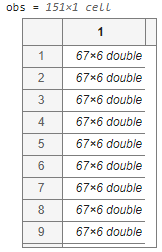

The *Testing_data* folder was initialized to contain the results from **Creating routes** section of waypoints preprocesing file.

### Saving the initial data for the RL network

Assign and save *fp_in* as the input file for the RL network. From *obs*, assign *fp_in* to contain all nested cell into a single double matrix. The dimensions of *fp_in* would vary depending on the number of flight and to the maximum length of longest route.

row_obs = size(obs, 1);
[row_flight,col_flights] = size(obs{1});

fp_in = zeros(row_flight, row_obs * col_flights);

for i = 1:row_obs
    first = (i-1) * col_flights + 1;
    last = i * col_flights;
    fp_in(:, first:last) = obs{i};
end
save('fp_in.mat', 'fp_in')